clearvars
%define the grid
Nx = 600;%600
Ny = 450;%450
dx = 2e-4;%2e-4
dy = 2e-4;%2e-4
Kgrid = kWaveGrid(Nx,dx,Ny,dy);
c = 1500;
%Kgrid.setTime

%Use point per wavelength ppl to reduce dx until stable
%dx = 2e-4 ppl = 37500
ppw = 40000;
wavelength = 1.5/120*Nx;
dx_new = wavelength/ppw

dx_new = 1.8750e-04

w = 1500/1e6%1.5mm

w = 0.0015

p = wavelength/dx

p = 37500


%define the medium prperty
medium.sound_speed = 1500;
medium.alpha_coeff = 0.75;
medium.alpha_power = 1.5;

% create the time array
Kgrid.makeTime(medium.sound_speed,0.3,6e-5);%128SQRT2/1500
t_array_new = Kgrid.t_array(1:126)

t_array_new = 1.0e-05 *

         0    0.0040    0.0080    0.0120    0.0160    0.0200    0.0240    0.0280    0.0320    0.0360    0.0400    0.0440    0.0480    0.0520    0.0560    0.0600    0.0640    0.0680    0.0720    0.0760    0.0800    0.0840    0.0880    0.0920    0.0960    0.1000    0.1040    0.1080    0.1120    0.1160    0.1200    0.1240    0.1280    0.1320    0.1360    0.1400    0.1440    0.1480    0.1520    0.1560    0.1600    0.1640    0.1680    0.1720    0.1760    0.1800    0.1840    0.1880    0.1920    0.1960



% define a single source point
source.p_mask = zeros(Nx, Ny);
source_x = 70/120*Nx;
source.p_mask(source_x, Ny/2) = 1;

% define a time varying sinusoidal source
source_freq = 1e6;   % [Hz]
source_mag = 3;         % [Pa]
source.p = source_mag * sin(2 * pi * source_freq * t_array_new);
%% 

% filter the source to remove high frequencies not supported by the grid
%source.p = filterTimeSeries(Kgrid, medium, source.p);

%define the sensor in a line
x_offset = 20/120*Nx % [grid points]

x_offset = 100

width = 50/90*Ny% [grid points]

width = 250

sensor.mask = zeros(Nx, Ny);
sensor.mask(x_offset, Ny/2 - width/2 + 1:7.8125:Ny/2 + width/2) = 1;

Running k-Wave simulation...
  start time: 08-Sep-2023 14:53:46
  reference sound speed: 1500m/s
  dt: 40ns, t_end: 60us, time steps: 1501
  input grid size: 600 by 450 grid points (120 by 90mm)
  maximum supported frequency: 3.75MHz
  precomputation completed in 0.083988s
  starting time loop...
  estimated simulation time 57.1281s...


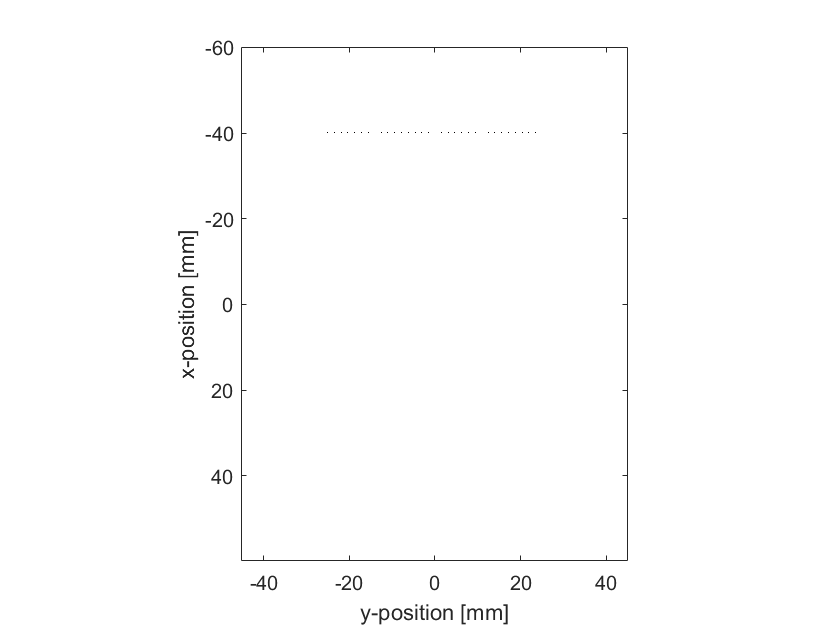

  simulation completed in 1min 0.47918s
  total computation time 1min 0.607s




% run the simulation
sensor_data = kspaceFirstOrder2D(Kgrid, medium, source, sensor);




% VISUALISATION
% =========================================================================

% plot the initial pressure and sensor distribution
%positive max around 0.043-0.0449
figure;
%imagesc(Kgrid.y_vec * 1e3, Kgrid.x_vec * 1e3, source.p0 + cart2grid(Kgrid, sensor.mask), [-1, 1]);
imagesc(source.p_mask + sensor.mask, [-1, 1]);
%imagesc(source.p0 + sensor.mask, [-1, 1]);
colormap(getColorMap);
ylabel('x-position');
xlabel('y-position');
axis image;

%% 


% plot the simulated sensor data
figure;
[t_sc, scale, prefix] = scaleSI(max(t_array_new));

subplot(2, 1, 1);
plot(source.p)
%plot(t_array_new * scale, source.p, 'k-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis ([-inf,inf,-inf,inf]);
title('Input Pressure Signal');

subplot(2, 1, 2);
plot(Kgrid.t_array * scale, sensor_data(32,:), 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis ([0,100,-0.05,0.05]);

%axis tight;
%axis([0,10.5,-inf,inf]);




%plot all the 32 original sensor signal 
figure
for i = 1:32
    subplot(32, 1, i);
    plot(Kgrid.t_array * scale, sensor_data(i,:), 'r-');

    %axis([0,10.5,-inf,inf]);
    set(gca,'XTick',[],'YTick',[]);
    if i == 1
            %xlabel(['Time [' prefix 's]']);
            ylabel('Signal Amplitude');
            title('Sensor Pressure Signal');
    end
    if i == 32 
        xlabel(['Time [' prefix 's]']);
        %ylabel('Signal Amplitude');
        %title('Sensor Pressure Signal');
    end

end

%% dt=40ns tend=100.04us timestep = 2502 totalt=1e-4
Kgrid.t_array

ans = 1.0e-04 *

         0    0.0004    0.0008    0.0012    0.0016    0.0020    0.0024    0.0028    0.0032    0.0036    0.0040    0.0044    0.0048    0.0052    0.0056    0.0060    0.0064    0.0068    0.0072    0.0076    0.0080    0.0084    0.0088    0.0092    0.0096    0.0100    0.0104    0.0108    0.0112    0.0116    0.0120    0.0124    0.0128    0.0132    0.0136    0.0140    0.0144    0.0148    0.0152    0.0156    0.0160    0.0164    0.0168    0.0172    0.0176    0.0180    0.0184    0.0188    0.0192    0.0196


t_array_limit = 1/source_freq*5

t_array_limit = 5.0000e-06

t_array_new = Kgrid.t_array(1:32)

t_array_new = 1.0e-05 *

         0    0.0040    0.0080    0.0120    0.0160    0.0200    0.0240    0.0280    0.0320    0.0360    0.0400    0.0440    0.0480    0.0520    0.0560    0.0600    0.0640    0.0680    0.0720    0.0760    0.0800    0.0840    0.0880    0.0920    0.0960    0.1000    0.1040    0.1080    0.1120    0.1160    0.1200    0.1240


1/2E-4

ans = 5000

128*1.414/1500

ans = 0.1207

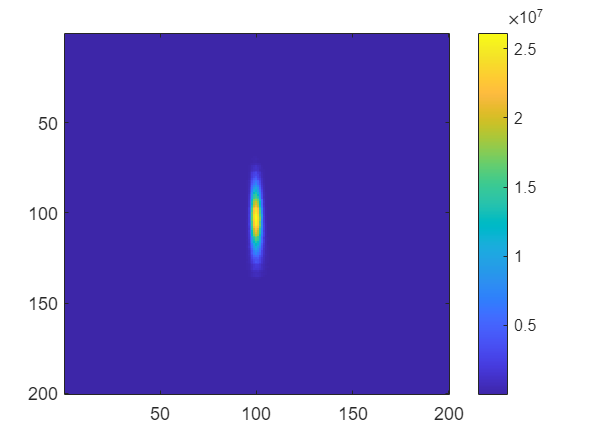

tic
%obtian all the sensor position
sensorpoistion = zeros(1,32);
j=1;
for i = 1:450
    if sensor.mask(100,i)==1
        
        sensorpoistion(j) = i;
        j = j+1;
    end
end
%sensorpoistion()

%distance from sensor to source mm
distance_map = zeros(1,32);
distance = zeros(1,32);
for i = 1:32
    distance(i) = sqrt((sensorpoistion(i)-225)^2+(350-100)^2);
end


%Create a 20mm times 20mm grid, which is 200 times 200
%x from 
map_length = zeros(1,200);
map_width = zeros(1,200);
%x_offset, Ny/2 - width/2 + 1:7.8125:Ny/2 + width/2
%source position

for i = 1:200
    map_length(i)=source_x-Nx/6+i;
    map_width(i)=225-20/90*Ny+i;
end
map_length;
map_width;


%the intensity map position

timespan = length(Kgrid.t_array);
tlength = 101;
sensor_timewindow = zeros(32,tlength);

step = zeros(1,32);
sensor_data_test = zeros(32,timespan);
sensor_data_new = zeros(32,timespan);
coeff = 4/32*pi;
%times distance with the sensor data3m

%define the energy map
energymap = zeros(200,200);

%ratio of the coherent sum to the incoherent sum

%distance from sensor to source mm
%distance_map = zeros(1,32);
%the map
intensitymap = zeros(1,1600);
for m = 1:200
     for n = 1:200
         A = zeros(32,tlength);
        for i = 1:32
            %calculate distance from each point
            timeshift = zeros(32,1);
            distance_map(1,i)=sqrt((sensorpoistion(i)-map_width(m))^2+(map_length(n)-100)^2);
            timeshift(i) = distance_map(i)*dx/c;
            timemin = floor(timeshift(i,:)/4e-8);
            timemax = timemin+tlength-1;
            if timemax>timespan
                timemax = timespan;
            end
            sensor_timewindow(i,:) = sensor_data(i,timemin:timemax);
            %sensor_data_sum = sum(sensor_timewindow)/32;
            %A(i,:) = distance_map(i)*sensor_timewindow(i,:);


            %apply the time delay to the sensor data
%             step(i) = floor(timeshift(i)/4e-8);
%             sensor_data_test(i,:) = sensor_data(i,:);
%             sensor_data_new(i,:) = circshift(sensor_data_test(i,:), -step(i));
            A(i,:) = sqrt(distance_map(i))*sensor_timewindow(i,:);
        end
        %sum 32 sensor data together
        sum_A = sum(A);
        
        %coherent sum
        Co_SUM =  sum_A.^2;

        %incoherent sum
        INCO_SUM = sum(A.^2);

        %coherence-factor
        CF = Co_SUM/INCO_SUM;

        %INTENSITY
        %intensity = coeff * sum_A;
        intensity= CF*sum_A;
       %integral'
%         Q = trapz(I);
%         energymap(n,m) = Q;
        %integral'
        intensity_2 = intensity.^2;
        Q = trapz(intensity_2);
        %coeff2 = 1/(4*pi*1500);
%         energymap(n,m)= intensity_2*intensity_2'/32/32*coeff2;
        %energymap(n,m)= Q*coeff2;
         energymap(n,m)= Q;
     end
end

figure

%imshow(energymap/256)

%imshow(uint8(energymap))
imagesc(energymap);
colorbar;  % colorbar 的作用是生成一个代表颜色值的条状图例

toc

历时 2.704566 秒。


% figure
% imshow(energymap,[])



% 
% figure
% 
% %imshow(energymap/256)
% 
% imshow(uint8(energymap))
% 
% rea = im2uint8(mat2gray(energymap));

% 
% figure
% imshow(rea)

%axial resolution
%index = 30:0.2:69.8;
middlepoint =(source_x)/2*0.2

middlepoint = 35

index = middlepoint-19.8:0.2:middlepoint+20;
axial = zeros(1,200);
for i = 1:200
    axial(i)= energymap(i,100);
end

% plot the value
figure;
[t_sc, scale, prefix] = scaleSI(max(map_length));


plot(index,axial,'r-')
%plot(t_array_new * scale, source.p, 'k-');
xlabel(['depth of source [mm]']);
ylabel('Energy');
axis ([-inf,inf,-inf,inf]);
title('Axial intensity');


% left value
leftEdge = find(axial >= 0.5*max(axial), 1, 'first')

leftEdge = 89


% right value
rightEdge = find(axial >= 0.5*max(axial), 1, 'last')

rightEdge = 116


% width
fwhmWidth = (rightEdge - leftEdge);

% 打印 FWHM 宽度
fprintf('FWHM width: %.2f mm', fwhmWidth);

FWHM width: 27.00 mm


axialcenter = find(axial == max(axial),1)

axialcenter = 102


%lateral resolution
index = 0.2:0.2:40;
lateral = zeros(1,200);
for i = 1:200
    lateral(i)= energymap(100,i);
end

% plot the value
figure;
[t_sc, scale, prefix] = scaleSI(max(map_width));


plot(index,lateral,'r-')
%plot(t_array_new * scale, source.p, 'k-');
xlabel(['width [mm]']);
ylabel('Energy');
axis ([-inf,inf,-inf,inf]);
title('Lateral intensity');


% left value
leftEdge = find(lateral >= 0.5*max(lateral), 1, 'first')

leftEdge = 98


% right value
rightEdge = find(lateral >= 0.5*max(lateral), 1, 'last')

rightEdge = 102


% width
fwhmLength = (rightEdge - leftEdge);

% 打印 FWHM 宽度
fprintf('FWHM width: %.2f mm', fwhmLength);

FWHM width: 4.00 mm

lateralcenter = find(lateral == max(lateral),1)

lateralcenter = 100